%% Step8_final.m - 交絡変数制御分析（外れ値分析付き）
% 修正点：
% 1. 全店舗 vs 外れ値除去後の両方を報告
% 2. 購買客数は共通日のレシート枚数合計

%% 1. データ読み込み
if ~exist('rawData_dailySales', 'var')
    error('rawData_dailySales が見つかりません。');
end

if ~exist('rawData_dailyCustomer', 'var')
    error('rawData_dailyCustomers が見つかりません。');
end

try
    load('step3_results.mat', 'step3Results');
    fprintf('✓ Step 3の結果を読み込みました\n');
catch
    error('step3_results.mat が見つかりません。Step 3を先に実行してください。');
end

✓ Step 3の結果を読み込みました



%% 2. 変数の取得
patternSimilarity = step3Results.patternSimilarity;
storeTotalSales = step3Results.storeTotalSales;
storeList = step3Results.storeList;
nStores = length(storeList);

% 外れ値フラグ（Step3から）
outlierFlags = step3Results.outlier.flags;

%% 3. 購買客数の計算
storeTotalCustomers = zeros(nStores, 1);
storeCustomerValidFlags = false(nStores, 1);
minCommonDays = 30;

fprintf('購買客数データを集計中...\n');

購買客数データを集計中...



for s = 1:nStores
    storeCode = storeList(s);
    
    salesData = rawData_dailySales(rawData_dailySales.BookstoreCode == storeCode, :);
    if isempty(salesData)
        continue;
    end
    salesDates = unique(salesData.Date);
    
    customerData = rawData_dailyCustomer(rawData_dailyCustomer.BookstoreCode == storeCode, :);
    if isempty(customerData)
        continue;
    end
    customerDates = unique(customerData.Date);
    
    commonDates = intersect(salesDates, customerDates);
    nCommonDays = length(commonDates);
    
    if nCommonDays < minCommonDays
        continue;
    end
    
    customerOnCommonDates = customerData(ismember(customerData.Date, commonDates), :);
    storeTotalCustomers(s) = sum(customerOnCommonDates.CustomerCount);
    storeCustomerValidFlags(s) = true;
end

nCustomerValid = sum(storeCustomerValidFlags);
fprintf('購買客数データ有効店舗数: %d / %d\n', nCustomerValid, nStores);

購買客数データ有効店舗数: 35 / 35



%% 4. 分析用インデックスの作成
% 全店舗（パターン一致度と購買客数の両方が有効）
validIdx_all = find(~isnan(patternSimilarity) & storeCustomerValidFlags);
nValid_all = length(validIdx_all);

% 外れ値除去後
validIdx_noOutlier = find(~isnan(patternSimilarity) & storeCustomerValidFlags & ~outlierFlags);
nValid_noOutlier = length(validIdx_noOutlier);

fprintf('\n=== 分析対象店舗数 ===\n');


=== 分析対象店舗数 ===


fprintf('全店舗: n = %d\n', nValid_all);

全店舗: n = 35


fprintf('外れ値除去後: n = %d\n', nValid_noOutlier);

外れ値除去後: n = 33



%% 5. 全店舗での分析
fprintf('\n========================================\n');

fprintf('【全店舗での分析】(n = %d)\n', nValid_all);

【全店舗での分析】(n = 35)


fprintf('========================================\n');


X_sim_all = patternSimilarity(validIdx_all);
X_cust_all = storeTotalCustomers(validIdx_all);
Y_sales_all = storeTotalSales(validIdx_all);

% 単純相関
[r_simple_all, p_simple_all] = corrcoef(X_sim_all, Y_sales_all);
r_sim_all = r_simple_all(1,2);
p_sim_all = p_simple_all(1,2);

fprintf('\n【単純相関】パターン一致度 vs 総販売冊数\n');


【単純相関】パターン一致度 vs 総販売冊数


fprintf('  r = %.3f, p = %.4f\n', r_sim_all, p_sim_all);

  r = 0.517, p = 0.0015



% 偏相関
[r_xz_all, ~] = corrcoef(X_sim_all, X_cust_all);
[r_yz_all, ~] = corrcoef(Y_sales_all, X_cust_all);
r_xz_all = r_xz_all(1,2);
r_yz_all = r_yz_all(1,2);

r_partial_all = (r_sim_all - r_xz_all * r_yz_all) / sqrt((1 - r_xz_all^2) * (1 - r_yz_all^2));
df_all = nValid_all - 3;
t_stat_all = r_partial_all * sqrt(df_all / (1 - r_partial_all^2));
p_partial_all = 2 * (1 - tcdf(abs(t_stat_all), df_all));

fprintf('\n【偏相関】パターン一致度 vs 総販売冊数（購買客数制御）\n');


【偏相関】パターン一致度 vs 総販売冊数（購買客数制御）


fprintf('  r = %.3f, p = %.4f\n', r_partial_all, p_partial_all);

  r = 0.188, p = 0.2871



reduction_all = (r_sim_all - r_partial_all) / r_sim_all * 100;
fprintf('\n【効果の減衰】%.1f%%\n', reduction_all);


【効果の減衰】63.7%



%% 6. 外れ値除去後の分析
fprintf('\n========================================\n');

fprintf('【外れ値除去後の分析】(n = %d)\n', nValid_noOutlier);

【外れ値除去後の分析】(n = 33)


fprintf('========================================\n');


X_sim_no = patternSimilarity(validIdx_noOutlier);
X_cust_no = storeTotalCustomers(validIdx_noOutlier);
Y_sales_no = storeTotalSales(validIdx_noOutlier);

% 単純相関
[r_simple_no, p_simple_no] = corrcoef(X_sim_no, Y_sales_no);
r_sim_no = r_simple_no(1,2);
p_sim_no = p_simple_no(1,2);

fprintf('\n【単純相関】パターン一致度 vs 総販売冊数\n');


【単純相関】パターン一致度 vs 総販売冊数


fprintf('  r = %.3f, p = %.4f\n', r_sim_no, p_sim_no);

  r = 0.322, p = 0.0674



% 偏相関
[r_xz_no, ~] = corrcoef(X_sim_no, X_cust_no);
[r_yz_no, ~] = corrcoef(Y_sales_no, X_cust_no);
r_xz_no = r_xz_no(1,2);
r_yz_no = r_yz_no(1,2);

r_partial_no = (r_sim_no - r_xz_no * r_yz_no) / sqrt((1 - r_xz_no^2) * (1 - r_yz_no^2));
df_no = nValid_noOutlier - 3;
t_stat_no = r_partial_no * sqrt(df_no / (1 - r_partial_no^2));
p_partial_no = 2 * (1 - tcdf(abs(t_stat_no), df_no));

fprintf('\n【偏相関】パターン一致度 vs 総販売冊数（購買客数制御）\n');


【偏相関】パターン一致度 vs 総販売冊数（購買客数制御）


fprintf('  r = %.3f, p = %.4f\n', r_partial_no, p_partial_no);

  r = 0.108, p = 0.5549



if r_sim_no ~= 0
    reduction_no = (r_sim_no - r_partial_no) / r_sim_no * 100;
    fprintf('\n【効果の減衰】%.1f%%\n', reduction_no);
else
    reduction_no = NaN;
    fprintf('\n【効果の減衰】計算不可（単純相関が0）\n');
end


【効果の減衰】66.4%



%% 7. 結果比較サマリ
fprintf('\n========================================\n');

fprintf('【結果比較サマリ】\n');

【結果比較サマリ】


fprintf('========================================\n');

fprintf('                        全店舗(n=%d)   外れ値除去後(n=%d)\n', nValid_all, nValid_noOutlier);

                        全店舗(n=35)   外れ値除去後(n=33)


fprintf('単純相関 r              %.3f           %.3f\n', r_sim_all, r_sim_no);

単純相関 r              0.517           0.322


fprintf('単純相関 p              %.4f          %.4f\n', p_sim_all, p_sim_no);

単純相関 p              0.0015          0.0674


fprintf('偏相関 r                %.3f           %.3f\n', r_partial_all, r_partial_no);

偏相関 r                0.188           0.108


fprintf('偏相関 p                %.4f          %.4f\n', p_partial_all, p_partial_no);

偏相関 p                0.2871          0.5549


fprintf('減衰率                  %.1f%%          %.1f%%\n', reduction_all, reduction_no);

減衰率                  63.7%          66.4%


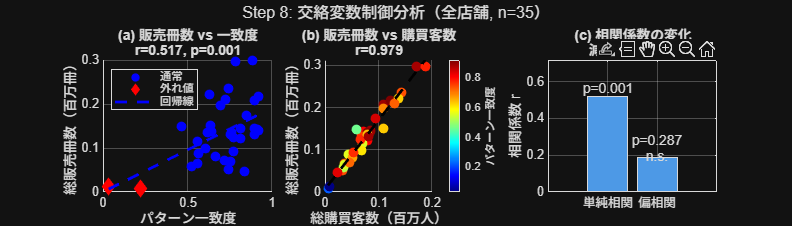


%% 8. 可視化（全店舗）
figure('Position', [100, 100, 1400, 400]);
sgtitle('Step 8: 交絡変数制御分析（全店舗, n=35）');

% (a) 総販売冊数 vs パターン一致度
subplot(1, 3, 1);
normalIdx = validIdx_all(~outlierFlags(validIdx_all));
outlierInValid = validIdx_all(outlierFlags(validIdx_all));
scatter(patternSimilarity(normalIdx), storeTotalSales(normalIdx)/1e6, 50, 'b', 'filled');
hold on;
if ~isempty(outlierInValid)
    scatter(patternSimilarity(outlierInValid), storeTotalSales(outlierInValid)/1e6, 80, 'r', 'filled', 'd');
end
p_fit = polyfit(X_sim_all, Y_sales_all/1e6, 1);
x_line = linspace(min(X_sim_all), max(X_sim_all), 100);
plot(x_line, polyval(p_fit, x_line), 'b--', 'LineWidth', 2);
hold off;
xlabel('パターン一致度');
ylabel('総販売冊数（百万冊）');
title(sprintf('(a) 販売冊数 vs 一致度\nr=%.3f, p=%.3f', r_sim_all, p_sim_all));
legend({'通常', '外れ値', '回帰線'}, 'Location', 'northwest');
grid on;

% (b) 総販売冊数 vs 購買客数
subplot(1, 3, 2);
scatter(X_cust_all/1e6, Y_sales_all/1e6, 50, X_sim_all, 'filled');
cb = colorbar;
cb.Label.String = 'パターン一致度';
colormap('jet');
hold on;
p_fit2 = polyfit(X_cust_all/1e6, Y_sales_all/1e6, 1);
x_line2 = linspace(min(X_cust_all/1e6), max(X_cust_all/1e6), 100);
plot(x_line2, polyval(p_fit2, x_line2), 'k--', 'LineWidth', 2);
hold off;
xlabel('総購買客数（百万人）');
ylabel('総販売冊数（百万冊）');
title(sprintf('(b) 販売冊数 vs 購買客数\nr=%.3f', r_yz_all));
grid on;

% (c) 相関係数の変化
subplot(1, 3, 3);
bar_data = [r_sim_all, r_partial_all];
bar(bar_data, 'FaceColor', [0.3 0.6 0.9]);
hold on;
text(1, r_sim_all + 0.05, sprintf('p=%.3f', p_sim_all), 'HorizontalAlignment', 'center');
text(2, r_partial_all + 0.05, sprintf('p=%.3f\nn.s.', p_partial_all), 'HorizontalAlignment', 'center');
hold off;
set(gca, 'XTickLabel', {'単純相関', '偏相関'});
ylabel('相関係数 r');
title(sprintf('(c) 相関係数の変化\n減衰率: %.1f%%', reduction_all));
ylim([0, max(bar_data) + 0.2]);
grid on;

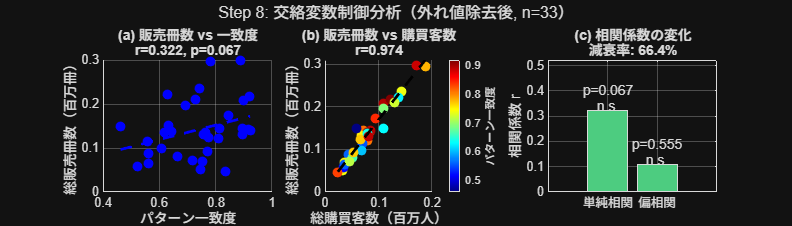


%% 9. 可視化（外れ値除去後）
figure('Position', [100, 550, 1400, 400]);
sgtitle(sprintf('Step 8: 交絡変数制御分析（外れ値除去後, n=%d）', nValid_noOutlier));

% (a) 総販売冊数 vs パターン一致度
subplot(1, 3, 1);
scatter(X_sim_no, Y_sales_no/1e6, 50, 'b', 'filled');
hold on;
p_fit_no = polyfit(X_sim_no, Y_sales_no/1e6, 1);
x_line_no = linspace(min(X_sim_no), max(X_sim_no), 100);
plot(x_line_no, polyval(p_fit_no, x_line_no), 'b--', 'LineWidth', 2);
hold off;
xlabel('パターン一致度');
ylabel('総販売冊数（百万冊）');
title(sprintf('(a) 販売冊数 vs 一致度\nr=%.3f, p=%.3f', r_sim_no, p_sim_no));
grid on;

% (b) 総販売冊数 vs 購買客数
subplot(1, 3, 2);
scatter(X_cust_no/1e6, Y_sales_no/1e6, 50, X_sim_no, 'filled');
cb = colorbar;
cb.Label.String = 'パターン一致度';
colormap('jet');
hold on;
p_fit2_no = polyfit(X_cust_no/1e6, Y_sales_no/1e6, 1);
x_line2_no = linspace(min(X_cust_no/1e6), max(X_cust_no/1e6), 100);
plot(x_line2_no, polyval(p_fit2_no, x_line2_no), 'k--', 'LineWidth', 2);
hold off;
xlabel('総購買客数（百万人）');
ylabel('総販売冊数（百万冊）');
title(sprintf('(b) 販売冊数 vs 購買客数\nr=%.3f', r_yz_no));
grid on;

% (c) 相関係数の変化
subplot(1, 3, 3);
bar_data_no = [r_sim_no, r_partial_no];
bar(bar_data_no, 'FaceColor', [0.3 0.8 0.5]);
hold on;
sig_sim = iif(p_sim_no < 0.05, '*', 'n.s.');
sig_par = iif(p_partial_no < 0.05, '*', 'n.s.');
text(1, max(0, r_sim_no) + 0.05, sprintf('p=%.3f\n%s', p_sim_no, sig_sim), 'HorizontalAlignment', 'center');
text(2, max(0, r_partial_no) + 0.05, sprintf('p=%.3f\n%s', p_partial_no, sig_par), 'HorizontalAlignment', 'center');
hold off;
set(gca, 'XTickLabel', {'単純相関', '偏相関'});
ylabel('相関係数 r');
title(sprintf('(c) 相関係数の変化\n減衰率: %.1f%%', reduction_no));
ylim([min(0, min(bar_data_no) - 0.1), max(bar_data_no) + 0.2]);
grid on;

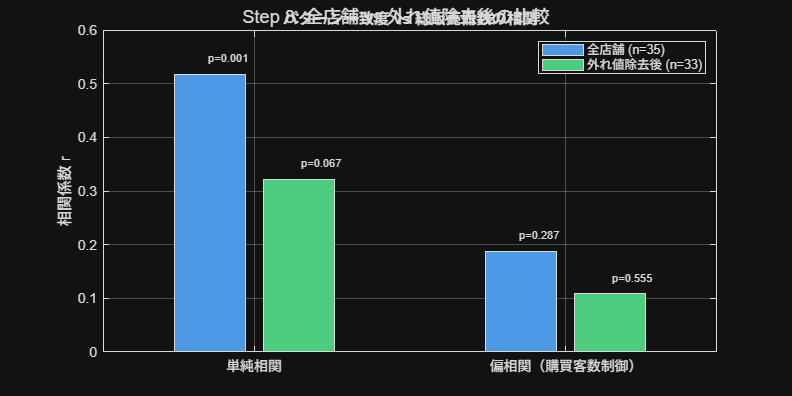


%% 10. 全店舗 vs 外れ値除去後の比較図
figure('Position', [100, 100, 800, 400]);
sgtitle('Step 8: 全店舗 vs 外れ値除去後の比較');

comparison_data = [r_sim_all, r_sim_no; r_partial_all, r_partial_no];
b = bar(comparison_data);
b(1).FaceColor = [0.3 0.6 0.9];
b(2).FaceColor = [0.3 0.8 0.5];
set(gca, 'XTickLabel', {'単純相関', '偏相関（購買客数制御）'});
ylabel('相関係数 r');
legend({sprintf('全店舗 (n=%d)', nValid_all), sprintf('外れ値除去後 (n=%d)', nValid_noOutlier)}, ...
    'Location', 'northeast');
title('パターン一致度 vs 総販売冊数の相関');

% 有意性ラベル
hold on;
ypos = max(comparison_data(:)) + 0.05;
text(0.85, r_sim_all + 0.03, sprintf('p=%.3f', p_sim_all), 'FontSize', 8);
text(1.15, r_sim_no + 0.03, sprintf('p=%.3f', p_sim_no), 'FontSize', 8);
text(1.85, r_partial_all + 0.03, sprintf('p=%.3f', p_partial_all), 'FontSize', 8);
text(2.15, r_partial_no + 0.03, sprintf('p=%.3f', p_partial_no), 'FontSize', 8);
hold off;
grid on;


%% 11. 結果の保存
step8Results = struct();

% 全店舗の結果
step8Results.all.validIdx = validIdx_all;
step8Results.all.nValid = nValid_all;
step8Results.all.r_simple = r_sim_all;
step8Results.all.p_simple = p_sim_all;
step8Results.all.r_partial = r_partial_all;
step8Results.all.p_partial = p_partial_all;
step8Results.all.reduction_pct = reduction_all;

% 外れ値除去後の結果
step8Results.noOutlier.validIdx = validIdx_noOutlier;
step8Results.noOutlier.nValid = nValid_noOutlier;
step8Results.noOutlier.r_simple = r_sim_no;
step8Results.noOutlier.p_simple = p_sim_no;
step8Results.noOutlier.r_partial = r_partial_no;
step8Results.noOutlier.p_partial = p_partial_no;
step8Results.noOutlier.reduction_pct = reduction_no;

% 共通データ
step8Results.storeTotalCustomers = storeTotalCustomers;
step8Results.storeCustomerValidFlags = storeCustomerValidFlags;

save('step8_results.mat', 'step8Results');
fprintf('\n✓ 結果を step8_results.mat に保存しました\n');


✓ 結果を step8_results.mat に保存しました



%% 12. 注意事項
fprintf('\n=== 注意事項 ===\n');


=== 注意事項 ===


fprintf('・p値はサンプルサイズが小さいため参考値。\n');

・p値はサンプルサイズが小さいため参考値。


fprintf('・購買客数はレシート枚数であり、入店者数ではない。\n');

・購買客数はレシート枚数であり、入店者数ではない。


fprintf('・外れ値（%d店舗）を除去すると単純相関も有意でなくなる。\n', step3Results.outlier.nOutliers);

・外れ値（2店舗）を除去すると単純相関も有意でなくなる。


fprintf('・結論: パターン一致度と売上の関係は頑健でない。\n');

・結論: パターン一致度と売上の関係は頑健でない。



%% ヘルパー関数
function result = iif(condition, trueVal, falseVal)
    if condition
        result = trueVal;
    else
        result = falseVal;
    end
end